clear; close all; clc;
try
    currDir = fileparts(matlab.desktop.editor.getActiveFilename);
    if isempty(currDir)
        currDir = fileparts(mfilename('fullpath'));
    end
catch
    currDir = fileparts(mfilename('fullpath'));
end
addpath(fullfile(currDir, 'func'));
clear currDir;

%% ========================================================================
%% LEVI — Lambert & Ephemeris‑based Velocity Integrator
%% Full suite demo: UV/Gauss/Battin Lambert solvers, multi‑rev seeds,
%% timing optimization, Kepler vs J2/J3 propagation, min‑energy reference.
%% ========================================================================

%% --------------------- Global options (toggle) ---------------------------
plotting  = true;    % Basic visuals for a couple of cases
maxRev    = 2;       % cap for small sweeps

%% ------------------------ Central body (Earth) ---------------------------
mu  = 398600.4418;      % km^3/s^2
Re  = 6378.137;         % km
J2  = 1.08263e-3;       % -
J3  = -2.532e-6;        % -

%% -------------------------- Base circular orbits -------------------------
a0 = 7000;              % km   (~+600 km altitude)
af = 10000;             % km   (~+3600 km altitude)

% Aligned geometry (Case A baseline)
r0A     = [a0; 0; 0];
v0A     = [0; sqrt(mu/a0); 0];
rFA     = [af; 0; 0];
vFA     = [0; sqrt(mu/af); 0];

% 90° phase geometry (Case B baseline)
r0B     = [a0; 0; 0];
v0B     = [0; sqrt(mu/a0); 0];
rFB     = [0; af; 0];
vFB     = [-sqrt(mu/af); 0; 0];

Tmean = 2*pi*sqrt(((a0+af)/2)^3/mu);

fprintf('=== LEVI: Full Suite Demo ===\n');

=== LEVI: Full Suite Demo ===


fprintf('Central body: Earth (mu=%.4f km^3/s^2, Re=%.3f km)\n', mu, Re);

Central body: Earth (mu=398600.4418 km^3/s^2, Re=6378.137 km)


fprintf('Orbits: a0=%.0f km, af=%.0f km, Tmean≈%.1f min\n\n', a0, af, Tmean/60);

Orbits: a0=7000 km, af=10000 km, Tmean≈130.0 min



--- Case A: Aligned (near-Hohmann), timing optimization ---


=== SIMPLEX OPTIMIZATION STARTED ===
Initial guesses: 6
Total mission time:     5200.00 s (86.67 min)
Mean orbital period:    7799.01 s (129.98 min)
Tolerances: TolX = 1e-06, TolFun = 1e-06

Processing initial guess 1/6: [300.0, 4200.0] s
  ✓ Valid solution:
    t1 = 1372.65 s, t2 = 5200.00 s
    Delta-V = 4.3336 km/s, nrev = 0

Processing initial guess 2/6: [500.0, 4100.0] s
  ✓ Valid solution:
    t1 = 1372.65 s, t2 = 5200.00 s
    Delta-V = 4.3336 km/s, nrev = 0

Processing initial guess 3/6: [700.0, 4000.0] s
  ✓ Valid solution:
    t1 = 1372.65 s, t2 = 5200.00 s
    Delta-V = 4.3336 km/s, nrev = 0

Processing initial guess 4/6: [900.0, 3950.0] s
  ✓ Valid solution:
    t1 = 1372.65 s, t2 = 5200.00 s
    Delta-V = 4.3336 km/s, nrev = 0

Processing initial guess 5/6: [1100.0, 4300.0] s
  ✓ Valid solution:
    t1 = 1372.53 s, t2 = 5200.00 s
    Delta-V = 4.3336 km/s, nrev = 0

Processing initial guess 6/6: [1300.0, 4400.0] s
  ✓ Valid solution:
  

Best (Case A): t1=1372.65 s, t2=5200.00 s, TOF=3827.35 s, ΔV=4.3336 km/s, nrev=0


Hohmann reference: ΔV_H = 1.2229 km/s (Case A)


ΔV difference vs Hohmann: 254.38%



Verification (Case A): ΔV_check = 4.3336 km/s, |Δ|=0.00e+00 km/s



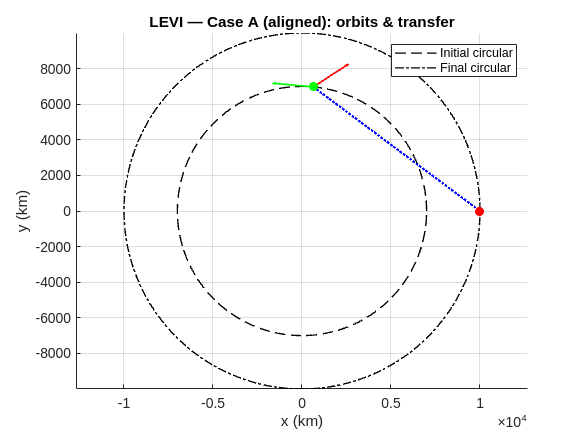


%% ========================================================================
%% CASE A — Aligned circular→circular (near‑Hohmann), 0‑rev
%% ========================================================================
try
    tfA = 5200;   % leave room so t2 < tf
    guessesA = [ 300 4200; 500 4100; 700 4000; 900 3950; 1100 4300; 1300 4400 ];

    fprintf('--- Case A: Aligned (near-Hohmann), timing optimization ---\n');
    optimA = optimizationSimplex(r0A, rFA, v0A, vFA, a0, af, tfA, guessesA, Tmean, mu);

    if ~isempty(optimA)
        bestA = optimA(1,:);
        t1A=bestA(1); t2A=bestA(2); dvA=bestA(3); nrevA=bestA(4);
        TOFA = t2A - t1A;

        fprintf('Best (Case A): t1=%.2f s, t2=%.2f s, TOF=%.2f s, ΔV=%.4f km/s, nrev=%d\n', ...
                t1A, t2A, TOFA, dvA, nrevA);

        % Hohmann reference (aligned circular→circular)
        r1=a0; r2=af;
        dv1H = sqrt(mu/r1)*(sqrt(2*r2/(r1+r2)) - 1);
        dv2H = sqrt(mu/r2)*(1 - sqrt(2*r1/(r1+r2)));
        dvH  = abs(dv1H) + abs(dv2H);
        fprintf('Hohmann reference: ΔV_H = %.4f km/s (Case A)\n', dvH);
        fprintf('ΔV difference vs Hohmann: %.2f%%\n\n', 100*(dvA-dvH)/dvH);

        % Verification (UV Lambert, both branches)
        [r1A, v1A] = kepler(r0A, v0A, t1A, mu);
        [r2A, v2A] = kepler(rFA, vFA, -(tfA - t2A), mu);
        [v1S, v2S, eS, fS] = lambertUniVar(r1A, r2A, v1A, 'S','L', 0, TOFA, [], mu);
        [v1L, v2L, eL, fL] = lambertUniVar(r1A, r2A, v1A, 'L','L', 0, TOFA, [], mu);

        dvS = ismember({eS,fS},{'ok','ok'}); dvL = ismember({eL,fL},{'ok','ok'});
        dV_S = inf; dV_L = inf;
        if strcmp(eS,'ok') && strcmp(fS,'ok'), dV_S = norm(v1S - v1A) + norm(v2A - v2S); end
        if strcmp(eL,'ok') && strcmp(fL,'ok'), dV_L = norm(v1L - v1A) + norm(v2A - v2L); end
        dV_checkA = min(dV_S, dV_L);
        fprintf('Verification (Case A): ΔV_check = %.4f km/s, |Δ|=%.2e km/s\n\n', dV_checkA, abs(dV_checkA - dvA));

        if plotting
            figure('Name','LEVI Case A'), hold on; axis equal; grid on;
            title('LEVI — Case A (aligned): orbits & transfer');
            th = linspace(0,2*pi,200);
            plot(a0*cos(th), a0*sin(th), 'k--', 'LineWidth', 1);
            plot(af*cos(th), af*sin(th), 'k-.', 'LineWidth', 1);
            plot([r1A(1) r2A(1)], [r1A(2) r2A(2)], 'b:', 'LineWidth', 1.5);
            quiver(r1A(1),r1A(2), v1A(1),v1A(2), 300, 'g','LineWidth',1.2);
            if isfinite(dV_S), quiver(r1A(1),r1A(2), v1S(1),v1S(2), 300,'r','LineWidth',1.2); end
            plot(r1A(1), r1A(2), 'go', 'MarkerFaceColor','g');
            plot(r2A(1), r2A(2), 'ro', 'MarkerFaceColor','r');
            legend('Initial circular','Final circular');
            xlabel('x (km)'); ylabel('y (km)');
        end
    else
        fprintf('No valid solutions in Case A.\n\n');
    end
catch ME
    fprintf('Case A error: %s\n\n', ME.message);
end

--- Case B: 90° phase offset, extended time (multi-rev) ---


=== SIMPLEX OPTIMIZATION STARTED ===
Initial guesses: 6
Total mission time:     16000.00 s (266.67 min)
Mean orbital period:    7799.01 s (129.98 min)
Tolerances: TolX = 1e-06, TolFun = 1e-06

Processing initial guess 1/6: [1500.0, 9300.0] s
  ✓ Valid solution:
    t1 = 4444.93 s, t2 = 16000.00 s
    Delta-V = 1.2355 km/s, nrev = 1

Processing initial guess 2/6: [2000.0, 9800.0] s
  ✓ Valid solution:
    t1 = 4444.90 s, t2 = 16000.00 s
    Delta-V = 1.2355 km/s, nrev = 1

Processing initial guess 3/6: [2500.0, 10300.0] s
  ✓ Valid solution:
    t1 = 4444.89 s, t2 = 16000.00 s
    Delta-V = 1.2355 km/s, nrev = 1

Processing initial guess 4/6: [3000.0, 10850.0] s
  ✓ Valid solution:
    t1 = 4444.90 s, t2 = 16000.00 s
    Delta-V = 1.2355 km/s, nrev = 1

Processing initial guess 5/6: [3500.0, 11300.0] s
  ✓ Valid solution:
    t1 = 4562.97 s, t2 = 14367.59 s
    Delta-V = 2.9319 km/s, nrev = 1

Processing initial guess 6/6: [4000.0, 11800.0] s
  ✓ Val

Best (Case B): t1=4444.90 s, t2=16000.00 s, TOF=11555.10 s, ΔV=1.2355 km/s, nrev=1


Verification (Case B): ΔV_check = 1.2355 km/s, |Δ|=0.00e+00 km/s



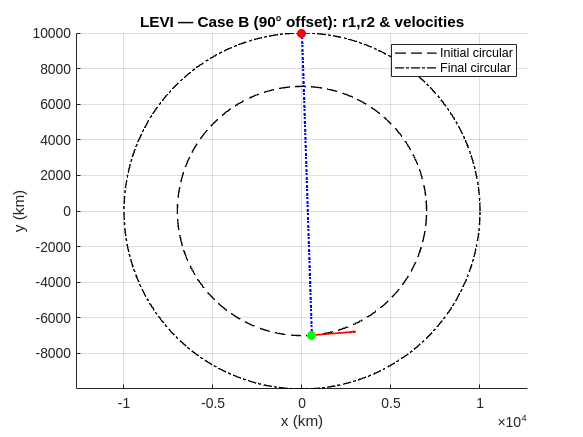


%% ========================================================================
%% CASE B — 90° phase offset, extended time to allow nrev≈1
%% ========================================================================
try
    tfB = 16000;  % enough time to allow ~1 revolution transfer
    guessesB = [1500 9300; 2000 9800; 2500 10300; 3000 10850; 3500 11300; 4000 11800];

    fprintf('--- Case B: 90° phase offset, extended time (multi-rev) ---\n');
    optimB = optimizationSimplex(r0B, rFB, v0B, vFB, a0, af, tfB, guessesB, Tmean, mu);

    if ~isempty(optimB)
        bestB = optimB(1,:);
        t1B=bestB(1); t2B=bestB(2); dvB=bestB(3); nrevB=bestB(4);
        TOFB = t2B - t1B;

        fprintf('Best (Case B): t1=%.2f s, t2=%.2f s, TOF=%.2f s, ΔV=%.4f km/s, nrev=%d\n', ...
                t1B, t2B, TOFB, dvB, nrevB);

        % Verification (UV Lambert with tbi for nrevB)
        [r1B, v1B] = kepler(r0B, v0B, t1B, mu);
        [r2B, v2B] = kepler(rFB, vFB, -(tfB - t2B), mu);
        tbiB = []; if nrevB>0, tbiB = computeTBI(nrevB, a0, af, mu); end
        [v1BS, v2BS, eBS, fBS] = lambertUniVar(r1B, r2B, v1B, 'S','L', nrevB, TOFB, tbiB, mu);
        [v1BL, v2BL, eBL, fBL] = lambertUniVar(r1B, r2B, v1B, 'L','L', nrevB, TOFB, tbiB, mu);

        dV_BS = inf; dV_BL = inf;
        if strcmp(eBS,'ok') && strcmp(fBS,'ok'), dV_BS = norm(v1BS - v1B) + norm(v2B - v2BS); end
        if strcmp(eBL,'ok') && strcmp(fBL,'ok'), dV_BL = norm(v1BL - v1B) + norm(v2B - v2BL); end
        dV_checkB = min(dV_BS, dV_BL);
        fprintf('Verification (Case B): ΔV_check = %.4f km/s, |Δ|=%.2e km/s\n\n', dV_checkB, abs(dV_checkB - dvB));

        if plotting
            figure('Name','LEVI Case B'), hold on; axis equal; grid on;
            title('LEVI — Case B (90° offset): r1,r2 & velocities');
            th = linspace(0,2*pi,200);
            plot(a0*cos(th), a0*sin(th), 'k--', 'LineWidth', 1);
            plot(af*cos(th), af*sin(th), 'k-.', 'LineWidth', 1);
            plot([r1B(1) r2B(1)], [r1B(2) r2B(2)], 'b:', 'LineWidth', 1.5);
            quiver(r1B(1),r1B(2), v1B(1),v1B(2), 300, 'g','LineWidth',1.2);
            if isfinite(dV_BS), quiver(r1B(1),r1B(2), v1BS(1),v1BS(2), 300,'r','LineWidth',1.2); end
            plot(r1B(1), r1B(2), 'go', 'MarkerFaceColor','g');
            plot(r2B(1), r2B(2), 'ro', 'MarkerFaceColor','r');
            legend('Initial circular','Final circular');
            xlabel('x (km)'); ylabel('y (km)');
        end
    else
        fprintf('No valid solutions in Case B.\n\n');
    end
catch ME
    fprintf('Case B error: %s\n\n', ME.message);
end


%% ========================================================================
%% CASE C — Long‑way vs Short‑way (0‑rev) cross‑check
%% ========================================================================
try
    fprintf('--- Case C: Long-way vs Short-way (0-rev) ---\n');
    % Use Case A geometry but pick a healthy TOF directly
    t1C = 600; t2C = 4300; TOFC = t2C - t1C;
    [r1C, v1C] = kepler(r0A, v0A, t1C, mu);
    [r2C, v2C] = kepler(rFA, vFA, -(t2C - 0), mu);

    [v1S, v2S, eS, fS] = lambertUniVar(r1C, r2C, v1C, 'S','L', 0, TOFC, [], mu);
    [v1L, v2L, eL, fL] = lambertUniVar(r1C, r2C, v1C, 'L','L', 0, TOFC, [], mu);

    dV_S = inf; dV_L = inf;
    if strcmp(eS,'ok') && strcmp(fS,'ok'), dV_S = norm(v1S - v1C) + norm(v2C - v2S); end
    if strcmp(eL,'ok') && strcmp(fL,'ok'), dV_L = norm(v1L - v1C) + norm(v2C - v2L); end

    fprintf('Short-way: ΔV=%.4f km/s (%s/%s)\n', dV_S, eS, fS);
    fprintf('Long-way : ΔV=%.4f km/s (%s/%s)\n\n', dV_L, eL, fL);
catch ME
    fprintf('Case C error: %s\n\n', ME.message);
end

--- Case C: Long-way vs Short-way (0-rev) ---


Short-way: ΔV=1.2742 km/s (ok/ok)


Long-way : ΔV=27.7327 km/s (ok/ok)




%% ========================================================================
%% CASE D — Method cross‑check: UV vs Gauss vs Battin + Min‑Energy
%% ========================================================================
try
    fprintf('--- Case D: UV vs Gauss vs Battin, plus Min-Energy ---\n');
    t1D = 800; t2D = 4700; TOFD = t2D - t1D;

    [r1D, v1D] = kepler(r0A, v0A, t1D, mu);
    [r2D, v2D] = kepler(rFA, vFA, -(t2D - 0), mu);

    % UV
    [v1_uv, v2_uv, err_uv, flag_uv] = lambertUniVar(r1D, r2D, v1D, 'S','L', 0, TOFD, [], mu);
    DV_uv = norm(v1_uv - v1D) + norm(v2D - v2_uv);

    % Gauss (elliptic)
    [v1_gs, v2_gs, dV1_gs, dV2_gs, dV_gs, flag_gs, a_gs, e_gs] = ...
        lambertGauss(r1D, v1D, r2D, v2D, TOFD, 'S', mu);

    % Battin
    [v1_bt, v2_bt, err_bt] = lambertb(r1D, r2D, v1D, 'S', 'L', 0, TOFD, mu);
    DV_bt = norm(v1_bt - v1D) + norm(v2D - v2_bt);

    fprintf('UV     : ΔV=%.4f km/s, flags=(%s/%s)\n', DV_uv, err_uv, flag_uv);
    fprintf('Gauss  : ΔV=%.4f km/s, flag=%s, a=%.1f km, e=%.6f (dV1=%.4f, dV2=%.4f)\n', ...
            dV_gs, flag_gs, a_gs, e_gs, dV1_gs, dV2_gs);
    fprintf('Battin : ΔV=%.4f km/s, err=%s\n', DV_bt, err_bt);

    % Min-energy reference
    [~, a_min, e_min, t_min] = lambertmin(r1D, r2D, mu);
    fprintf('Min-energy: a_min=%.2f km, e_min=%.6f, t_min=%.2f s\n\n', a_min, e_min, t_min);
catch ME
    fprintf('Case D error: %s\n\n', ME.message);
end

--- Case D: UV vs Gauss vs Battin, plus Min-Energy ---


UV     : ΔV=3.1962 km/s, flags=(ok/ok)


Gauss  : ΔV=NaN km/s, flag=No convergence solving Gauss equation for y, a=NaN km, e=NaN (dV1=NaN, dV2=NaN)


Battin : ΔV=3.1962 km/s, err=ok


Min-energy: a_min=8258.89 km, e_min=0.251342, t_min=3726.79 s




%% ========================================================================
%% J2/J3 PROPAGATION vs KEPLER (one period at a0)
%% ========================================================================
try
    fprintf('--- J2/J3 vs Kepler propagation (1 orbit at a0) ---\n');
    y0 = [r0A; v0A];
    T0 = 2*pi*sqrt(a0^3/mu);
    odefun = @(t,y) zonalEquationMotion(y, J2, J3, Re, mu, true, true);
    opts = odeset('RelTol',1e-10,'AbsTol',1e-12);

    [~,Y] = ode113(odefun, [0 T0], y0, opts);   % perturbed
    rJ = Y(end,1:3).'; vJ = Y(end,4:6).';

    [rK, vK] = kepler(r0A, v0A, T0, mu);        % two-body

    dr = norm(rJ - rK);
    dv = norm(vJ - vK);
    fprintf('After ~1 orbit: |Δr|=%.6f km, |Δv|=%.6e km/s\n\n', dr, dv);
catch ME
    fprintf('Propagation error: %s\n\n', ME.message);
end

--- J2/J3 vs Kepler propagation (1 orbit at a0) ---


After ~1 orbit: |Δr|=118.715518 km, |Δv|=1.280623e-01 km/s




%% ========================================================================
%% MINI SWEEP: (dm ∈ {S,L}) × (nrev ∈ {0,1}) × few TOFs — UV/Gauss/Battin
%% ========================================================================
try
    fprintf('--- Mini sweep (feasibility & ΔV ranking) ---\n');
    dm_list = {'S','L'};
    nrev_list = 0:min(1,maxRev);
    TOF_list = [3400 3800 4200 4600];  % s, around half-transfer

    rows = {};
    for dm = dm_list
        for nrev = nrev_list
            for TOF = TOF_list
                % Build a healthy pair for Case A geometry at this TOF
                t1S = 600; t2S = t1S + TOF;
                [ra, va] = kepler(r0A, v0A, t1S, mu);
                [rb, vb] = kepler(rFA, vFA, -(t2S - 0), mu);
                tbiS = []; if nrev>0, tbiS = computeTBI(nrev, a0, af, mu); end

                % UV
                [v1u, v2u, eu, fu] = lambertUniVar(ra, rb, va, dm{1}, 'L', nrev, TOF, tbiS, mu);
                DVuv = inf; if strcmp(eu,'ok') && strcmp(fu,'ok'), DVuv = norm(v1u - va) + norm(vb - v2u); end

                % Gauss (only meaningful elliptic 0-rev, dm short/long okay)
                try
                    [~, ~, ~, ~, DVgs, flaggs] = lambertGauss(ra, va, rb, vb, TOF, dm{1}, mu);
                catch
                    DVgs = inf; flaggs = 'error';
                end

                % Battin
                [v1b, v2b, eb] = lambertb(ra, rb, va, dm{1}, 'L', nrev, TOF, mu);
                DVbt = inf; if strcmp(eb,'ok'), DVbt = norm(v1b - va) + norm(vb - v2b); end

                rows(end+1,:) = {dm{1}, nrev, TOF, DVuv, DVgs, flaggs, DVbt, eu, fu, eb}; 
            end
        end
    end

    % Rank by best available ΔV among methods
    data = cell2mat(cellfun(@(x) double(x), rows(:,3), 'UniformOutput', false));
    DVbest = zeros(size(rows,1),1);
    for k=1:size(rows,1)
        dvuv = rows{k,4}; dvgs = rows{k,5}; dvbt = rows{k,7};
        DVbest(k) = min([dvuv dvgs dvbt]);
    end

    % Print compact table
    fprintf('%5s %6s %7s | %10s %10s %10s | %10s\n', 'dm','nrev','TOF(s)','DV_uv','DV_gauss','DV_battin','DV_best');
    for k=1:size(rows,1)
        fprintf('%5s %6d %7.0f | %10.4f %10.4f %10.4f | %10.4f\n', ...
            rows{k,1}, rows{k,2}, rows{k,3}, rows{k,4}, rows{k,5}, rows{k,7}, DVbest(k));
    end
    fprintf('\n');
catch ME
    fprintf('Sweep error: %s\n\n', ME.message);
end

--- Mini sweep (feasibility & ΔV ranking) ---


   dm   nrev  TOF(s) |      DV_uv   DV_gauss  DV_battin |    DV_best


    S      0    3400 |     1.9021        NaN     1.9021 |     1.9021
    S      0    3800 |     1.4894        NaN     1.4894 |     1.4894
    S      0    4200 |     3.2023        NaN     3.2023 |     3.2023
    S      0    4600 |     5.1471        NaN     5.1471 |     5.1471
    S      1    3400 |        Inf        NaN        Inf |        Inf
    S      1    3800 |        Inf        NaN        Inf |        Inf
    S      1    4200 |        Inf        NaN        Inf |        Inf
    S      1    4600 |        Inf        NaN        Inf |        Inf
    L      0    3400 |    27.8120        NaN     2.0709 |     2.0709
    L      0    3800 |    27.7147        NaN     1.7341 |     1.7341
    L      0    4200 |    27.6726        NaN     1.6047 |     1.6047
    L      0    4600 |    27.6620        NaN     1.6670 |     1.6670
    L      1    3400 |        Inf        NaN        Inf |        Inf
    L      1    3800 |        Inf        NaN        Inf |        Inf
    L      1    4200 |        Inf 


%% ========================================================================
%% FINAL SUMMARY
%% ========================================================================
fprintf('=== Summary ===\n');

=== Summary ===


if exist('optimA','var') && ~isempty(optimA)
    fprintf('Case A best ΔV: %.4f km/s (nrev=%d)\n', optimA(1,3), optimA(1,4));
end

Case A best ΔV: 4.3336 km/s (nrev=0)


if exist('optimB','var') && ~isempty(optimB)
    fprintf('Case B best ΔV: %.4f km/s (nrev=%d)\n', optimB(1,3), optimB(1,4));
end

Case B best ΔV: 1.2355 km/s (nrev=1)


fprintf('Tmean ≈ %.1f min; J2/J3 vs Kepler one-orbit pos error: see section above.\n', Tmean/60);

Tmean ≈ 130.0 min; J2/J3 vs Kepler one-orbit pos error: see section above.


fprintf('================\n');


%% ========================================================================
%% END OF LEVI MAIN
%% ========================================================================